# input data

file='C:\Users\PhotonUser\My Files\Temporary Files\Lab4BodePlot.txt';
fileID=fopen(file);
textstuff=textscan(fileID, '%s %s %s','Delimiter','\t');
fclose(fileID);

## organize and separate frequency data

freq=textstuff{1,1};
freq=string(freq);
freq=freq(4:26);
freq=str2double(freq);
freq=2.*pi.*freq;

## organize and separate gain data

gain=textstuff{1,2};
gain=string(gain);
gain=gain(4:26);
gain=str2double(gain);

## organize and separate phase shift data

phase=textstuff{1,3};
phase=string(phase);
phase=phase(4:26);
phase=str2double(phase);

## measured data

f=[3.183,9.549,31.83,95.49,318.3];
f=2.*pi.*f;
g=[0.993,0.937,0.683,0.303,0.0965];
g=20*log10(g);
p=[-6.188,-15.126,-42.627,-75.628,-77.9198];

## theoretical gain data

ft=linspace(3.183,477.45,100);
ft=2.*pi.*ft;
wrc=ft.*10000.*0.000001;
wrc2=(wrc).^2;
ur=wrc2+1;
root=sqrt(ur);
il=1./root;
tg=20.*log10(il);

## theoretical phase shift data

it=ft.*10000.*0.000001;
tpr=-1.*atan(it);
tp=tpr.*180./pi;

## gain plot

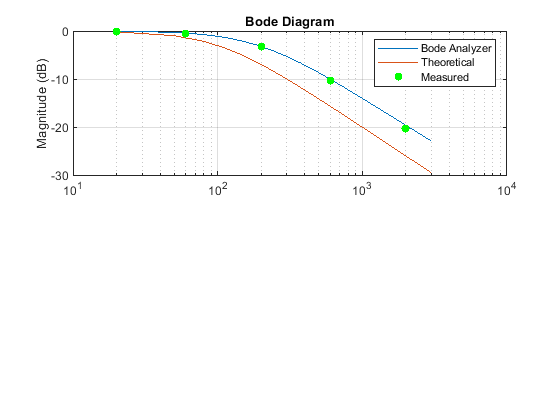

subplot(2,1,1);
semilogx(freq,(gain),'DisplayName','Bode Analyzer')
hold on
plot(ft,tg,'DisplayName','Theoretical')
hold on
scatter(f(1),g(1),'filled','g','DisplayName','Measured')
hold on
scatter(f(2),g(2),'filled','g')
hold on
scatter(f(3),g(3),'filled','g')
hold on
scatter(f(4),g(4),'filled','g')
hold on
scatter(f(5),g(5),'filled','g')
hold on
grid on
ylabel('Magnitude (dB)')
title('Bode Diagram')
legend('Bode Analyzer','Theoretical','Measured')
hold off

## phase shift plot

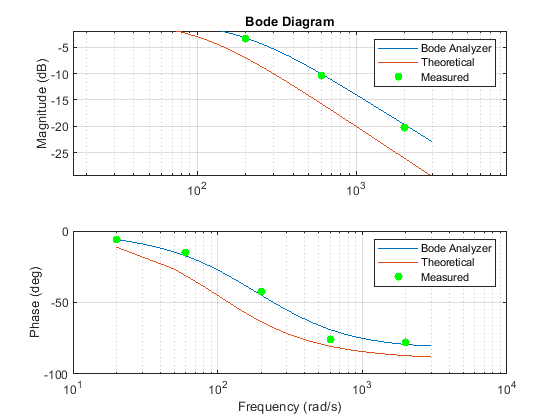

subplot(2,1,2)
semilogx(freq,phase,'DisplayName','Bode Analyzer')
hold on 
plot(ft,tp,'DisplayName','Theoretical')
hold on
scatter(f(1),p(1),'filled','g')
hold on
scatter(f(2),p(2),'filled','g','DisplayName','Measured')
hold on
scatter(f(3),p(3),'filled','g')
hold on
scatter(f(4),p(4),'filled','g')
hold on
scatter(f(5),p(5),'filled','g')
hold on
grid on 
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Bode Analyzer','Theoretical','Measured')
hold off